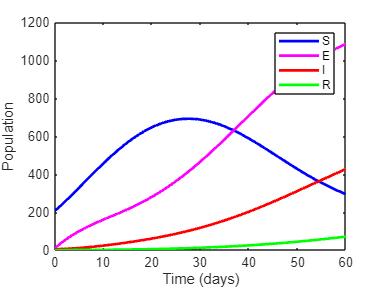

clc; clear; close all;

%% ==============================
%% TIME SPAN
%% ==============================
tspan = [0 60];

%% ==============================
%% INITIAL CONDITIONS [S E I R C P]
%% ==============================
y0 = [205 10 5 0 100 50];

%% ==============================
%% PARAMETERS (BASELINE: NO CONTROL)
%% ==============================
p.Lambda = 50;
p.mu = 0.018;

p.betaP0 = 0.02;
p.betaC0 = 0.002;
p.d = 0.04;

p.omega0 = 0.04;
p.sigma = 0.005;
p.eta = 0.01;

% NO CONTROL
p.v = 0;
p.epsilon = 0;
p.kappa = 0;

p.a = 0.1;
p.K2 = 1e6;
p.psi = 0.0303;
p.h = 0.018;
p.delta = 0.2;
p.theta = 0.002;

p.Topt = 25;
p.sigmaT = 5;
p.aR = 0.3;
p.h0 = 0.5;
p.Mopt = 0.6;

%% ==============================
%% SOLVE SYSTEM
%% ==============================
[t,y] = ode45(@(t,y) model_full(t,y,p), tspan, y0);

S = y(:,1); E = y(:,2); I = y(:,3);
R = y(:,4); C = y(:,5); P = y(:,6);

%% ==============================
%% 1. TIME SERIES
%% ==============================
figure;
plot(t,S,'b',t,E,'m',t,I,'r',t,R,'g','LineWidth',2);
legend('S','E','I','R');
xlabel('Time (days)');
ylabel('Population');

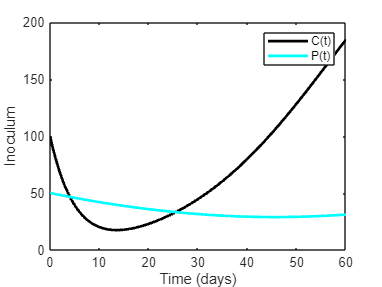

%%title('Baseline Dynamics (No Control)');

figure;
plot(t,C,'k',t,P,'c','LineWidth',2);
legend('C(t)','P(t)');
xlabel('Time (days)');
ylabel('Inoculum');

%%title('Environmental Reservoirs');

%% ==============================
%% 2. PEAK INFECTION
%% ==============================
[I_peak, idx] = max(I);
t_peak = t(idx);

fprintf('Peak infection = %.2f\n', I_peak);

Peak infection = 426.27


fprintf('Time to peak = %.2f days\n', t_peak);

Time to peak = 60.00 days



%% ==============================
%% 3. TIME TO ENDEMIC EQUILIBRIUM
%% ==============================
tol = 1e-5;
dI = abs(diff(I));
eq_idx = find(dI < tol,1);

if ~isempty(eq_idx)
    fprintf('Time to endemic equilibrium ≈ %.2f days\n', t(eq_idx));
else
    fprintf('Equilibrium not reached\n');
end

Equilibrium not reached



%% ==============================
%% MODEL FUNCTION (INSIDE SAME FILE)
%% ==============================
function dydt = model_full(t,y,p)

S = y(1); E = y(2); I = y(3);
R = y(4); C = y(5); P = y(6);

%% Climate (constant baseline)
T = 25;
Rain = 5;
H = 0.7;
M = 0.6;

fT = exp(-((T - p.Topt)^2)/(2*p.sigmaT^2));
fR = 1 - exp(-p.aR*Rain);
fH = H/(H + p.h0);
fM = min(1, M/p.Mopt);

%% Transmission
betaP = p.betaP0 * fM;
betaC = p.betaC0 * fR * fH;

lambda = betaP * (P/(p.d + P)) + betaC * C;

%% Progression
omega = p.omega0 * fT * fH * fM;

%% System
dS = p.Lambda - lambda*S - p.mu*S;
dE = lambda*S - (omega + p.mu)*E;
dI = omega*E - (p.sigma + p.mu + p.v + p.eta)*I;
dR = (p.v + p.eta)*I - p.mu*R;

dC = p.a*I*(1 - C/p.K2) + p.psi*(P/(p.h + P)) - p.delta*C;
dP = p.theta*(1 - p.v)*I - (p.mu + p.kappa)*P;

dydt = [dS; dE; dI; dR; dC; dP];

end